%WING AND ENGINE SIZING
u = symunit;  % u_c = double(separateUnits(unitConvert(100*u.knot, u.m/u.s))),% knot-->m/s / cruise speed, m/s
e = 0.85;
c_D0 = 0.03; 
sigma = 0.861; 
AR = 7; 
eta = 0.7; 
c_Lmax = 1.5; 
C_DG=0.06;
C_LR=1.24; 
miu = 0.04;               
V_max = 129.59*u.knot;
v_s = 43.1965*u.knot;
m = 1763.698*u.lb;                                                                                                                  
ro_0 = 0.002378*u.slug/u.ft^3; 
ro = 0.002048*u.slug/u.ft^3; 
ro_C = 0.001755*u.slug/u.ft^3;                                                                  
g = 32.1850*u.ft/u.s^2; 
S_TO = 1312.34*u.ft; 
ROC = 984.252*u.ft/u.s;                                                                                               
% SI
ro_ = double(separateUnits(unitConvert(ro,'SI'))); ro_0_ = double(separateUnits(unitConvert(ro_0,'SI')));
ro_C_ = double(separateUnits(unitConvert(ro_C,'SI')));
v_s_= double(separateUnits(unitConvert(v_s,'SI'))); V_max_=double(separateUnits(unitConvert(V_max,'SI')));
g_ = double(separateUnits(unitConvert(g, 'SI'))); S_TO_ = double(separateUnits(unitConvert(S_TO,'SI')));
ROC_ = double(separateUnits(unitConvert(ROC, 'SI'))); m_ = double(separateUnits(unitConvert(m,'SI'))); 

ro_0 = double(separateUnits(ro_0)); ro = double(separateUnits(ro)); ro_C = double(separateUnits(ro_C));
V_max = double(separateUnits(V_max)); v_s = double(separateUnits(v_s)); m = double(separateUnits(m));                           
g = double(separateUnits(g)); S_TO = double(separateUnits(S_TO)); ROC = double(separateUnits(ROC));
%STALL SPEED
 WS_stall = 0.5 * ro * (v_s * 1.688)^2 * c_Lmax;
 WS_stall = double(separateUnits(WS_stall))

WS_stall = 8.1664

% SI
WS_stall_ = 0.5 * ro_ *v_s_^2 * c_Lmax        %(N/m2)     

WS_stall_ = 390.9236

%MAXIMUM SPEED
K = 1 / (pi * e * AR) ;                                                                                                                                                                
WS = 0:0.1:50;                                                                                                                                                                                        
WP_Vmax = eta * 550 ./(0.5 * ro_0 * (V_max * 1.688)^3 * c_D0 ./WS + 2 * K / (ro * sigma * (V_max * 1.688)) * WS);
% SI          
WS_ = 0:10:1000;                                                                                         %SI (N/M^2)  ;                                                                          
WP_Vmax_ = eta ./(0.5 * ro_0_ * V_max_^3 * c_D0 ./WS_ + 2 * K / (ro_ * sigma * V_max_) * WS_);     % SI (N/W);

%TAKEOFF RUN
 V_TO = 1.1 * v_s;
WP_STO = (1 - exp(0.6 * ro * g * C_DG * S_TO ./ WS)) ./ (miu -(miu + C_DG / C_LR) * exp(0.6 * ro * g * C_DG * S_TO ./ WS)) * eta / V_TO/1.688 * 550;
% SI
V_TO_ = 1.1 * v_s_ ;                                                                                                                                                                        
WP_STO_ = (1 - exp(0.6 * ro_ * g_ * C_DG * S_TO_ ./ WS_)) ./ (miu -(miu + C_DG / C_LR) * exp(0.6 * ro_ * g_ * C_DG * S_TO_ ./ WS_)) * eta / V_TO_

WP_STO_ =        NaN    0.3240    0.3239    0.3228    0.3197    0.3148    0.3086    0.3017    0.2944    0.2870    0.2795    0.2722    0.2651    0.2582    0.2515    0.2451    0.2390    0.2331    0.2274    0.2220    0.2168    0.2118    0.2071    0.2025    0.1981    0.1939    0.1898    0.1859    0.1822    0.1786    0.1751    0.1718    0.1685    0.1654    0.1624    0.1595    0.1568    0.1541    0.1514    0.1489    0.1465    0.1441    0.1418    0.1396    0.1374    0.1354    0.1333    0.1314    0.1295    0.1276



%RATE OF CLIMB
LD_max = 1 / 2 / sqrt(K * c_D0);
WP_ROC = 1 ./ (ROC / 60 / eta + sqrt(2 / (ro * sqrt(3 * c_D0 / K)) * WS) * (1.155 / LD_max / eta)) * 550;
% SI
WP_ROC_ = 1 ./ (ROC_ / 60 / eta + sqrt(2 / (ro_ * sqrt(3 * c_D0 / K)) * WS_) * (1.155 / LD_max / eta))

WP_ROC_ =     0.1400    0.1308    0.1273    0.1247    0.1226    0.1209    0.1193    0.1179    0.1167    0.1155    0.1144    0.1134    0.1124    0.1115    0.1107    0.1099    0.1091    0.1084    0.1077    0.1070    0.1064    0.1057    0.1051    0.1045    0.1040    0.1034    0.1029    0.1024    0.1019    0.1014    0.1009    0.1004    0.1000    0.0995    0.0991    0.0987    0.0983    0.0979    0.0975    0.0971    0.0967    0.0964    0.0960    0.0956    0.0953    0.0949    0.0946    0.0943    0.0940    0.0936


%ABSOLUTE CEILING
sigma_C = ro_C / ro_0  ;                                                                                                                                                                       
WP_C = sigma_C ./ (sqrt(2 / (ro_C * sqrt(3 * c_D0 / K)) * WS) * (1.155 / LD_max / eta)) * 550;
% SI
sigma_C_ = ro_C_ / ro_0_  ;                                                                                                                                                                 
WP_C_ = sigma_C_ ./ (sqrt(2 / (ro_C_ * sqrt(3 * c_D0 / K)) * WS_) * (1.155 / LD_max / eta))

WP_C_ =        Inf    1.3520    0.9560    0.7806    0.6760    0.6046    0.5520    0.5110    0.4780    0.4507    0.4276    0.4077    0.3903    0.3750    0.3613    0.3491    0.3380    0.3279    0.3187    0.3102    0.3023    0.2950    0.2883    0.2819    0.2760    0.2704    0.2652    0.2602    0.2555    0.2511    0.2468    0.2428    0.2390    0.2354    0.2319    0.2285    0.2253    0.2223    0.2193    0.2165    0.2138    0.2112    0.2086    0.2062    0.2038    0.2015    0.1993    0.1972    0.1951    0.1931



%WING AND ENGINE SIZING DIAGRAM
figure;
sp1 =subplot(2,1,1); hold on;             
    plot(WS,WP_Vmax, 'r-','lineWidth',2); 
    plot(WS,WP_STO,'--','lineWidth',2);                                                                                      
    plot(WS,WP_ROC,'g--','linewidth',2); 
    plot(WS,WP_C,'m:','linewidth',2);                                                                                         
    plot([WS_stall WS_stall],[0 400],'r--','LineWidth',2);                                                                                                                         
grid on; title('Wing and Engine Sizing (Imperial Units)'); 
xlabel('W/S (lb/ft^2)'); 
ylabel('W/P (lb/hp)'); ylim([0 150]);                          
legend({'V_{max}';'S_{TO}'; 'ROC';'Abs. Ceil';'V_{stall}'},'Location','best');                                                                                    
% SI
sp2=subplot(2,1,2); yyaxis left; hold on;                                                                                                                                             
    plot(WS_,WP_Vmax_,'r-','LineWidth',2); 
    plot(WS_,WP_STO_,'b--','LineWidth',2);                                                                    
   plot(WS_,WP_ROC_,'g--','LineWidth',2); 
   plot(WS_,WP_C_,'m:','LineWidth',2);                                                                            
    plot([WS_stall_ WS_stall_],[0 1],'r--','linewidth',2);                                                                 
grid on; title('Wing and Engine Sizing (SI Units)'); 
xlabel('W/S (N/m^2)'); 
ylabel('W/P (N/W)'); ylim([0 1]);                                     


%EVALUATION OF HIGH LIFT DEVICES INFLUENCE
V_stall_min_ = 0.5 * v_s_; v_stall_max_ = 1.1 * v_s_; v_stall_=V_stall_min_:(v_stall_max_-V_stall_min_)/4:v_stall_max_;  
axes(sp2); yyaxis right; hold on; ylim([0 3]); C_L_Stall =[]; ylabel('C_{Lmax}'); col=['b';'r';'y';'g';'m']; 
for i=1:length(v_stall_), C_L_Stall = 2 * WS_ / ro_ / v_stall_(i)^2; plot(WS_, C_L_Stall,'LineStyle','-.','Color',col(i),'Marker','none'); end                              

%DESIGN POINT [W/S_OPT, W/P_OPT]  Imperial Units
Obj = @(x, WS, WP_Vmax, WP_STO, WP_ROC, WP_C) ...                                                                                                               
        -min([interp1(WS,WP_Vmax,x),interp1(WS,WP_STO,x),interp1(WS,WP_ROC,x),interp1(WS,WP_C,x)]);               
   [WS_opt, WP_opt] = fmincon(@(x) Obj(x, WS, WP_Vmax, WP_STO, WP_ROC, WP_C), WS_stall/2,[],[],[],[],0, WS_stall_);        % design point
 disp(['Design Point: WS_opt = ' num2str(WS_opt) ' lb/hp;  WP_opt = ' num2str(-WP_opt) ' lb/hp']);                                                                  
 


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Design Point: WS_opt = 16.8535 lb/hp;  WP_opt = 14.3503 lb/hp


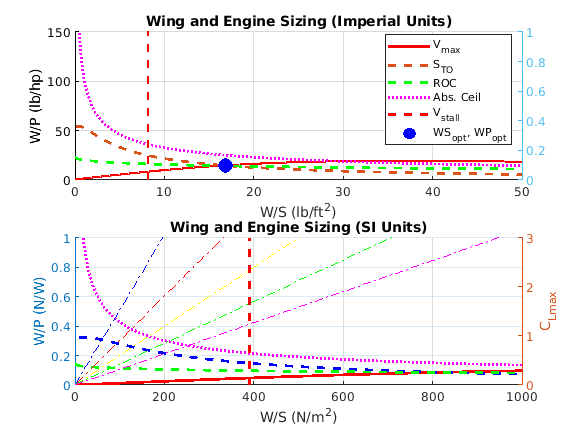

 axes(sp1); 
 yyaxis left; 
 hold on; 
 plot(WS_opt,-WP_opt,'bo','MarkerSize',10,"MarkerFaceColor",'b');                                                        
legend(sp1,{'V_{max}';'S_{TO}'; 'ROC';'Abs. Ceil';'V_{stall}';('WS_{opt}, WP_{opt}');...                                                                                 
    ['V_s=' num2str(v_stall_(1))];['V_s=' num2str(v_stall_(2))];['V_s=' num2str(v_stall_(3))];...                                                                      
     ['V_s=' num2str(v_stall_(4))];['V_s=' num2str(v_stall_(5))]},'Location','best');



%DESIGN OF UNMANNED AERIAL SYSTEMS

WPd_=1763.7/WS_opt

WPd_ = 104.6492

WSd_=1763.7/(-1*WP_opt)

WSd_ = 122.9034

 disp(['Answer: Engine power is: = ' num2str(WPd_) 'hp ']);

Answer: Engine power is: = 104.6492hp 


  disp(['Answer: Wing area is: = ' num2str(WSd_) 'm2']);

Answer: Wing area is: = 122.9034m2



WP_Vmaxx = eta * 550 ./(0.5 * ro_0 * (V_max * 1.688)^3 * c_D0 ./WS_stall + 2 * K / (ro * sigma * (V_max * 1.688)) * WS_stall)

WP_Vmaxx = 8.0234

WP_STOo = (1 - exp(0.6 * ro * g * C_DG * S_TO ./ WS_stall)) ./ (miu -(miu + C_DG / C_LR) * exp(0.6 * ro * g * C_DG * S_TO ./ WS_stall)) * eta / V_TO/1.688 * 550

WP_STOo = 24.9201

WP_ROCc = 1 ./ (ROC / 60 / eta + sqrt(2 / (ro * sqrt(3 * c_D0 / K)) * WS_stall) * (1.155 / LD_max / eta)) * 550

WP_ROCc = 16.2717

WP_ceill = sigma_C ./ (sqrt(2 / (ro_C * sqrt(3 * c_D0 / K)) * WS_stall) * (1.155 / LD_max / eta)) * 550

WP_ceill = 36.2469